clear; close all;

# Tutorial: Synthetic Star Image

This example will demonstrate how to create a synthetic image using SONIC. In particular, this will be a synthetic image of the star Arcturus, and its surrounding starfield.

To generate an accurate synthetic image of a starfield, a variety of tools are required. First, star information must be drawn from a star catalog, manipulated via some representation of attitude, and then projected into a camera frame. For physical correctness, stellar aberration must be applied to these projected stars. These stars must then be processed through a camera model (including appropriate distortion!). 

From scratch, this can require a great deal of boilerplate code to simply generate a synthetic image. SONIC wraps most of this functionality into a couple of lines of code per step.

This tutorial will provide example usage of SONIC's `Camera`, `DistortionModel` (here, `BrownConrady`), `Attitude`, `StarCatalog` (here, `Hipparcos`), `Aberration`, `Project`, `PointsS2`, and `Points2` classes. For these (and all) SONIC classes, each constructor and method is annotated, and these annotations are accessible via the `help` command. For example,

help sonic.BrownConrady

  obj = BrownConrady(p1,p2,k1,k2,k3)
    Constructs a BrownConrady object, which contains the parameters 
    of the Brown Conrady camera distortion model 
    
    Inputs:
        p1  (1x1) double - Vertical decentering 
        p2  (1x1) double - Horizontal decentering
        k1  (1x1) double - Order 2 radial distortion
        k2  (1x1) double - Order 4 radial distortion
        k3  (1x1) double - Order 6 radial distortion 
 
    Outputs:
        - obj (sonic.BrownConrady): BrownConrady object, encoding a
        the parameters of the distortion model 
 
    Last revised: 2/21/24
    Last author: Ava Thrasher

    Documentation for sonic.BrownConrady



### Setting up a Camera

The first step to capturing a synthetic image is to create a camera model. In SONIC, a camera object is composed of camera intrinsics and a distortion model. 

For the purposes of this tutorial, OSIRIS-REx's MapCam will be used as a baseline. The instrument kernel for MapCam **[1] **([found here](https://naif.jpl.nasa.gov/pub/naif/ORX/kernels/ik/orx_ocams_v07.ti)) details the FOV and resolution of the camera. In SONIC, this information can be used to instantiate a camera object. A distortion model must also be specified to instantiate a camera object. If no distortion is desired, then a `sonic.Pinhole` model can be specified. While the OSIRIS-REx mission didn't publish a calibration of MapCam to the instrument kernel during cruise, a Brown-Conrady model with some arbitrary values is instantiated for illustrative purposes.

The full-angle FOV from the instrument kernel is given to be 3.97 degrees.

hfov_DEG = 3.97;

SONIC provides several unit conversions (see `sonic.Units`), among them degrees to radians.

hfov_RAD = sonic.Units.DEGtoRAD(hfov_DEG);

Resolution from the instrument kernel is 1024 by 1024.

xres = 1024;
yres = 1024;

And finally, the distortion model and camera can be instantiated,

dist_model = sonic.BrownConrady(0.023, 0.002, 0.8, 0.05, 0);
cam = sonic.Camera(hfov_RAD, 'fov', 'h', [yres, xres], dist_model);

This is not the only way to instantiate a camera in SONIC. It may also be instantiated directly from a camera calibration matrix, or using the IFOV of the sensor. See the following documentation for details.

help sonic.Camera.constructFromFOV

  obj = constructFromFOV(obj, fov, fov_type, direction, res, dist_model)
    
    Creates a model for a framing camera using information about 
    the camera's FOV or instantaneous FOV, as well as sensor 
    resolution. Also consumes a distortion model. Note that x/y 
    directions here coorespond with the canonical camera
    model, i.e.: +z along boresight, +x to the right looking out of
    the camera, +y down looking out of the camera. As well, u/v
    cooresponds to x/y directions, but is centered in the top-left
    of the image. 
 
    NOTE: When constructing a camera model with this method, square
    pixels and no shear are assumed. If this is not the case,
    construct the camera model directly from the camera intrinsics.
    
    Inputs:
        - fov (1x1 double): Field-of-view or IFOV, in radians. In
        either case, these are full-angle values.
        - fov_type (1x1 string): String specifying whether the
        previous argument was an FOV ('fo

help sonic.Camera.constructFromK

  obj = constructFromK(obj, d_x, d_y, alpha, u_p, v_p, dist_model)
    
    Creates a model for a framing camera using elements of the
    camera calibration matrix. Also consumes a distortion model. 
    Note that x/y directions here coorespond with the canonical 
    camera model, i.e.: +z along boresight, +x to the right looking
    out of the camera, +y down looking out of the camera. As well, 
    u/v cooresponds to x/y directions, but is centered in the 
    top-left of the image.
    
    Inputs:
        - d_x (1x1 double): Focal length/pixel pitch, x direction
        - d_y (1x1 double): Focal length/pixel pitch, y direction
        - alpha (1x1 double): Pixel shear 
        - u_p (1x1 double): Center point, u coordinates (pixels)
        - v_p (1x1 double): Center point, v coordinates (pixels)
        - dist_model (1x1 sonic.DistortionModel): Distortion model
        used to transform projected points prior to being passed
        through the camera intrinsics

### Defining Camera Attitude, Position, Velocity, and Imaging Epoch

With the camera initialized, some thought must be given to the position and attitude of the camera in space, as well as the epoch of the image capture. The epoch and observer position become important in the following section when acquiring star unit vectors (on the celestial sphere). The attitude is used to bring these unit vectors into the camera frame. Velocity is also considered, so as to incorporate the effects of stellar aberration.

Note that in SONIC, the scene geometry (here, a set of star unit vectors, originally in ICRF) is manipulated into the camera frame, rather than manipulating the camera position and attitude in the scene.

For this example, suppose the observer is along the ICRF x-axis, at a distance of 1.1 AU from the origin, with a velocity of 29.783 km/s (a circular orbit about the sun). The image is captured on January 1st, 2024, at 12:00 AM UTC. In SONIC, observation time is measured consistently with SPICE (i.e., seconds in TDB since the J2000 epoch), and thus the desired epoch is expressed in SPICE time below. Also suppose that the camera is oriented such that Arcturus is in the center of the frame (the provided attitude accomplishes this). 

In SONIC, the Attitude class conveniently enables creation of an Attitude object from many representations (run `help sonic.Attitude` for more information), and then precomputes and stores other popular representations in the object for easy access. When inputting an attitude with a quaternion, the convention must be specified to be scalar-first or -last to avoid ambiguity. Here we choose to input scalar-last and input the appropriate flag to specify this convention.

The attitude (ICRF to Camera frame) to observer Arcturus is given.

att_ICRFtoCam = sonic.Attitude([0.323290008; -0.480763528; 0; 0.815076683], 'vs');

The observer position and velocity are declared.

r_obs_AU = [1.1; 0; 0]; 
v_obs_KMS = [0;29.783;0];

And the observation epoch (in SPICE time) is also specified.

t_img = 7.573392691839061e+08; % = Jan 1, 2024, 00:00 UTC

### Acquiring Star Unit Vectors

Before projecting stars into an image, it's necessary to acquire the positions of stars on the celestial sphere. SONIC comes equipped with the Hipparcos catalog, which can be loaded with a single line.

hip_cat = sonic.Hipparcos();

This catalog can easily be filtered, either via a logical vector of catalog indices or a list of catalog indices. For example, suppose the camera can see down to visual magnitude 8. This effect can be simulated by filtering the catalog to only contain stars of magnitude 8 or brighter.

hip_cat = hip_cat.filter(hip_cat.Vmag < 8);

For practical purposes, the 5-parameter standard model **[2]** may be used to evaluate star unit vectors at an arbitrary observation time and observer position. The 5-parameter standard model is (independent of units)


$$\mathbf{e} = < \mathbf{e}_0  + (t - t_{ep}) (\mu_a \mathbf{p} + \mu_\delta \mathbf{q}) - \varpi \mathbf{r}(t)>$$


where the angle brackets yield the unit vector of the quantity they contain, and:


$$\mathbf{e}_0 = \text{star ICRF unit vector at catalog epoch}

$$



$$t = \text{imaging epoch}$$



$$t_{ep} = \text{catalog epoch}$$



$$\mu_a = \text{proper motion in the right ascension direction}$$



$$\mathbf{p} = \text{right ascension direction in LVLH frame}$$



$$\mu_\delta = \text{proper motion in the declination direction}$$



$$\mathbf{q} = \text{declination direction in LVLH frame}$$



$$\varpi = \text{annual parallax}$$



$$\mathbf{r}(t) = \text{observer ICRF position}$$


Recall that SONIC expresses observation time consistently with SPICE, with observer position measured in AU in ICRF. Thus, to evaluate the standard model for the catalog, one can simply call the catalog's `eval()` function. 

stars_u = hip_cat.eval(t_img, r_obs_AU);

This returns a `PointsS2` (i.e., points lying on the 2-sphere) object containing the locations of the evaluated stars, in ICRF, at the desired epoch and relative to the specified observer location. 

### Generate Synthetic Image

Now, the `Camera` object's `synthImage` method may be invoked, incorporating the star unit vectors in the inertial frame, the camera itself, and knowledge of the camera's pose and velocity. Internally, the `synthImage` method consumes the unit vectors, rotates them into the camera frame, projects them into the image plane, applies stellar aberration, distorts the points per the specified distortion model, and converts the resultant points to pixel coordinates. The method returns a `Points2` object containing the resultant star locations in pixel coordinates, as well as a second logical vector mapping the provided list of points (`stars_u`) to those that end up projecting into the image (`stars_img`).

[stars_img, did_proj] = cam.synthImage(stars_u, att_ICRFtoCam, v_obs_KMS);

A helper function is declared below that consumes the output of the synthetic image and provides a simple visualization (scaling the stars according to magnitude). SONIC does not focus on visualization, but the outputs of these processes may be easily processed by a variety of standard MATLAB plotting routines, as is the case here. Tooltips provide the Hipparcos IDs and constellations of the stars in the image, as well as Bayer designations (if applicable). 

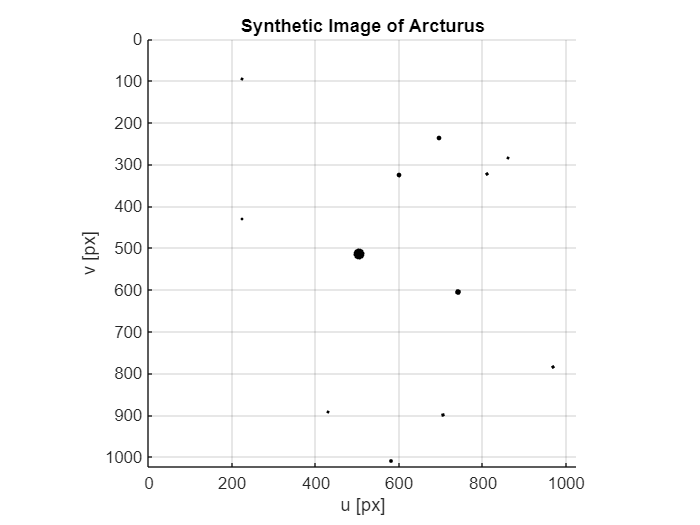

plotHipparcosImage(stars_img, did_proj, hip_cat, cam);

Thus, excluding the plotting code below, SONIC provides a complete synthetic star image generation pipeline in 15 lines of code or less.

### Plotting Helper Function:

function plotHipparcosImage(stars_img, did_proj, hip_cat, cam)

    % Plot the stars, size corresponding to magnitude (brighter = bigger)
    figure;
    s = scatter(stars_img.r2(1, :), stars_img.r2(2, :), 5.*(8.5-hip_cat.Vmag(did_proj)), 'k', 'filled');
    
    % Add some helpful tooltip info:
    hip_info = [dataTipTextRow('Hip ID', double(hip_cat.id(did_proj))), ...
                dataTipTextRow('V Mag', hip_cat.Vmag(did_proj)), ...
                dataTipTextRow('Bayer Des', strcat(hip_cat.bayer(did_proj), ...
                upper(hip_cat.const_bayer(did_proj)))), ...
                dataTipTextRow('Const', hip_cat.const_radec(did_proj))];
    s.DataTipTemplate.DataTipRows(end) = [];
    s.DataTipTemplate.DataTipRows(end+1:end+4) = hip_info;
    
    % Format the axes:
    axis equal;
    xlim([0, 2.*cam.u_p]);
    ylim([0, 2.*cam.v_p]);
    set(gca, 'YDir', 'reverse');
    grid on;

    % Add labels:
    title('Synthetic Image of Arcturus');
    xlabel('u [px]');
    ylabel('v [px]');

end

### References

**[1] **OSIRIS-REx SPICE Kernel Archive Bundle, Semenov B. V.; Costa Sitja M.; Bailey A. M., [https://www.doi.org/10.17189/1520435](https://www.doi.org/10.17189/1520435) (2023)

**[2]** The Hipparcos and Tycho Catalogues. European Space Agency, ESA SP-1200 (1997)